% a clear MATLAB workspace is a clear mental workspace
close all; clear
% pkg load statistics % load Octave stats package

## create some data distributions

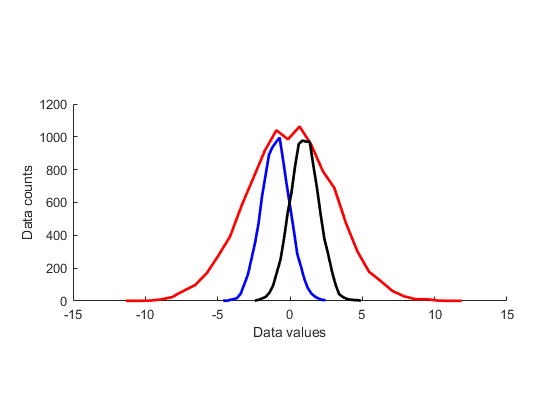

% the distributions
N = 10001; % number of data points
nbins = 30; % number of histogram bins

d1 = randn(N,1) - 1;
d2 = 3*randn(N,1);
d3 = randn(N,1) + 1;

% need their histograms
[y1,x1] = hist(d1,nbins);

[y2,x2] = hist(d2,nbins);

[y3,x3] = hist(d3,nbins);


% plot them
figure(1), clf
subplot(5,1,2:4), hold on

plot(x1,y1,'b','linewidth',2)
plot(x2,y2,'r','linewidth',2)
plot(x3,y3,'k','linewidth',2)

xlabel('Data values')
ylabel('Data counts')

## overlay the mean

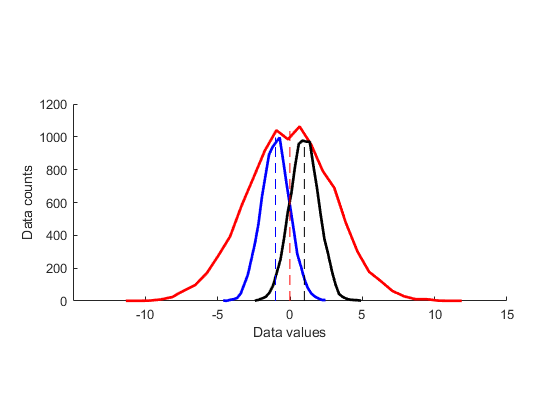

% compute the means
mean_d1 = sum(d1) / length(d1);
mean_d2 = mean(d2);
mean_d3 = mean(d3);

% plot them
plot([1 1]*mean_d1,[0 max(y1)],'b--')
plot([1 1]*mean_d2,[0 max(y2)],'r--')
plot([1 1]*mean_d3,[0 max(y3)],'k--')

## "failure" of the mean

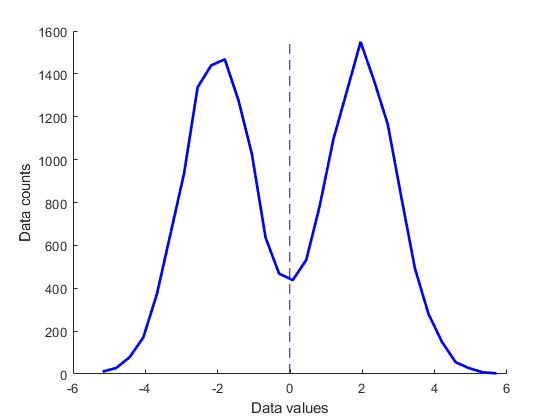

% new dataset of distribution combinations
d4 = [ randn(N,1)-2; randn(N,1)+2 ];
% and its histogram
[y4,x4] = hist(d4,nbins);

% and its mean
mean_d4 = mean(d4);


figure(2), clf, hold on
plot(x4,y4,'b','linewidth',2)
plot([1 1]*mean_d4,[0 max(y4)],'b--')

xlabel('Data values')
ylabel('Data counts')

## median

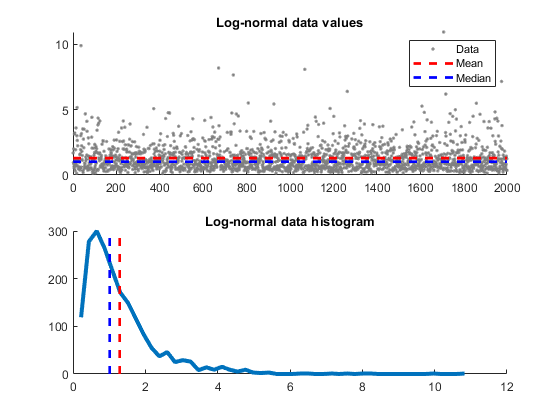

% create a log-normal distribution
shift   = 0;
stretch = .7;
n       = 2000;
nbins   = 50;

% generate data
data = stretch*randn(n,1) + shift;
data = exp( data );

% and its histogram
[y,x] = hist(data,nbins);

% compute mean and median
datamean = mean(data);
datamedian = median(data);


% plot data
figure(3), clf
subplot(211), hold on
plot(data,'.','color',[1 1 1]*.5)
plot([1 n],[1 1]*datamean,'r--','linewidth',2)
plot([1 n],[1 1]*datamedian,'b--','linewidth',2)
legend({'Data';'Mean';'Median'})
title('Log-normal data values')

subplot(212), hold on
plot(x,y,'linew',3)
plot([1 1]*datamean,[0 max(y)],'r--','linewidth',2)
plot([1 1]*datamedian,[0 max(y)],'b--','linewidth',2)
title('Log-normal data histogram')

## mode

data = round(randn(1,10))

data =     -1    -2    -2     0     1    -1     0    -1    -1    -2



uniq_data = unique(data);
for i=1:length(uniq_data)
    disp([ num2str(uniq_data(i)) ' appears ' num2str(sum(data==uniq_data(i))) ' times.' ])
end

-2 appears 3 times.
-1 appears 4 times.
0 appears 2 times.
1 appears 1 times.



disp([ 'The modal value is ' num2str(mode(data)) ])

The modal value is -1


## done.